%this is for propeller
wp=40

wp = 40

we_w0=0.4

we_w0 = 0.4000

wc_w0=0.1

wc_w0 = 0.1000

Range=150*1000     %in metres

Range = 150000

sfc_cruise_prop=(0.6)*1.689e-7*9.8

sfc_cruise_prop = 9.9313e-07

sfc_loiter_prop=(0.7)*1.689e-7*9.8

sfc_loiter_prop = 1.1587e-06

velocity_cruise=500*5/18

velocity_cruise = 138.8889

velocity_loiter=250*5/18

velocity_loiter = 69.4444

Endurance=20*60 %in seconds

Endurance = 1200

L_D=6:14

L_D =      6     7     8     9    10    11    12    13    14


np=0.7  %propeller

np = 0.7000

w3_w2=zeros(length(L_D),1);
w5_w4=zeros(length(L_D),1);
w1_w0=0.98

w1_w0 = 0.9800

w2_w1=0.97

w2_w1 = 0.9700

for i=1:length(L_D)
    w3_w2(i)=exp(-(Range*sfc_cruise_prop/(np*L_D(i))));
end
w3_w2

w3_w2 =     0.9652
    0.9701
    0.9737
    0.9766
    0.9789
    0.9808
    0.9824
    0.9838
    0.9849


w4_w3=0.99

w4_w3 = 0.9900

for i=1:length(L_D)
    w5_w4(i)=exp(-(Endurance*sfc_loiter_prop*velocity_loiter/(np*L_D(i))));
end
w5_w4

w5_w4 =     0.9773
    0.9805
    0.9829
    0.9848
    0.9863
    0.9875
    0.9886
    0.9894
    0.9902


w6_w5=0.997

w6_w5 = 0.9970

w6_w0=w1_w0*w2_w1*w4_w3*w6_w5*(w3_w2.*w5_w4)

w6_w0 =     0.8850
    0.8924
    0.8980
    0.9024
    0.9059
    0.9088
    0.9112
    0.9133
    0.9151


wf_w0=1.05*(1-w6_w0);
w0=zeros(length(L_D),1);
r=(1-wf_w0-we_w0-wc_w0);
for i=1:length(L_D)
    w0(i)=wp/r(i);
end
w0

w0 =   105.4732
  103.3496
  101.8010
  100.6218
   99.6939
   98.9448
   98.3272
   97.8094
   97.3690


wf=wf_w0.*w0

wf =    12.7366
   11.6748
   10.9005
   10.3109
    9.8470
    9.4724
    9.1636
    8.9047
    8.6845


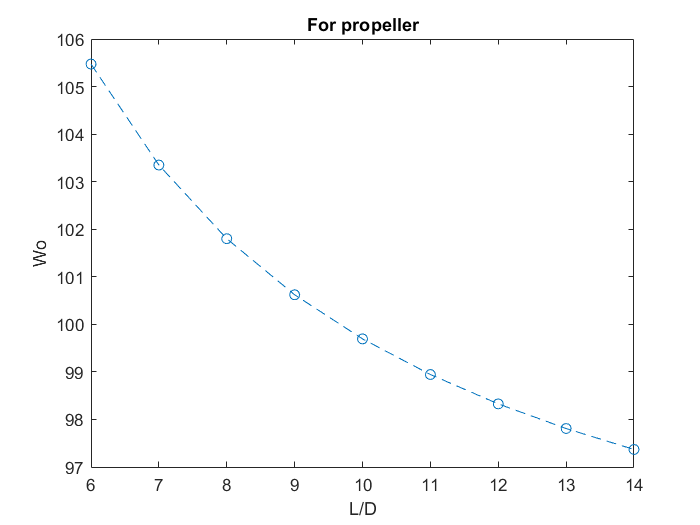

plot(L_D,w0,"LineStyle","--","Marker","o")
title("For propeller")
xlabel("L/D")
ylabel("Wo")

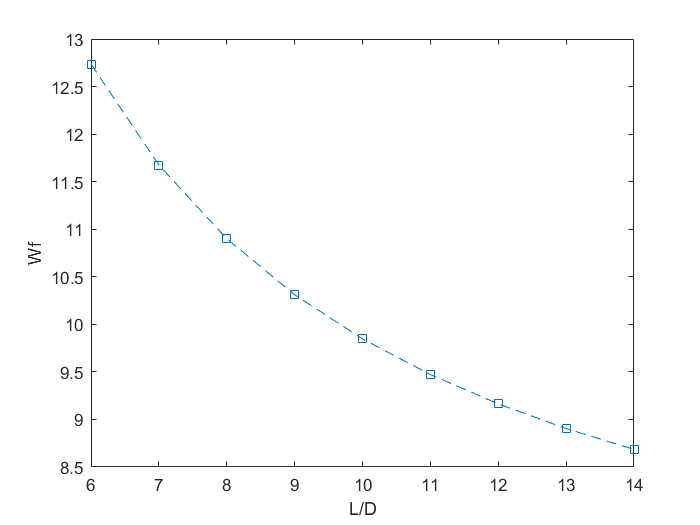

plot(L_D,wf,"LineStyle","--","Marker","square")
xlabel("L/D")
ylabel("Wf")